# Microstructure in EEG signals

3B group: Giuseppe Leo, Marco Baldari

## Introduction

While previous research supported the notions that brain functions are localized in hierarchically distinct areas and information is processed in a feed-forward manner, more recent studies have indicated that individual brain functions involve massive parallel processing in distributed brain networks. 'Microstates' in the brain are defined as successive short time periods during which the configuration of the scalp potential field remains semi-stable, suggesting quasi-simultaneity of activity among the nodes of large-scale networks. A few prototypic microstates, can be reliably identified across people. Researchers have proposed that these microstates represent the basic building blocks of the chain of spontaneous conscious mental processes, and that their occurrence and temporal dynamics determine the quality of mentation. Several studies have further demonstrated that disturbances of mental processes associated with neurological and psychiatric conditions manifest as changes in the temporal dynamics of specific microstates. (3)

In this project we analyze the microstates using Principal Component Analysis, Cluster Analysis and Hidden Markov Model.

clc
clear all

## **Data Loading**

The dataset is made of 2 EEG signals recorded with 64 electrodes, belonging to two different volunteers. we can choose between each other and then confront the results. All of our considerations are on the person 1.

person = "1";
if person=='1'
[hdr, record] = edfread('S011R02.edf');
else
[hdr, record] = edfread('S001R02.edf');
end

Step 1 of 2: Reading requested records. (This may take a few minutes.)...
Step 2 of 2: Parsing data...


v=record(1:end-1,:);
N=length(record(1,:));
C=length(v(:,1));
fc=160;
time = (0:(N-1))./fc;
cols = {'r','g','b','c','m','k','y'};

## Plot of EEG data

Switching checksignals on '0' we can display the signals from the 64 channels (only grafical purpose). 

default: checksignals=1.

checksignals = "1";
if checksignals == '0'
figure('Position',[0 0 2000 50*C])
%sgtitle('Plot of EEG data')
for n = 1:C
    subplot(C,1,n)
    plot(time,v(n,:),'color','r');
    box off
    ylabel(hdr.label(n),'Rotation',0,'FontSize',5)
    yticks([])
    xticks([])
    xlim([0 60])
end
xticks([0 10 20 30 40 50 60])
xlim([0 60])
xlabel('Time [s]')
end

We don't filter the signal because we don't want to lose information.

## Computing GFP signal

Global brain activity can be described by the global field power (GFP). The GFP represents the strength of the electric field over the brain at each instant (EEG), and so is often used to measure the global brain response to an event or to characterize the rapid changes in brain activity. Local maxima of GFP curve represent instants of strongest field strength and highest topographic signal-to-noise ratio.(1)


$$GFP=\ \ \sqrt{\frac{{\left(\sum_i^K \left.{\left(V_i {\left(t\right)}-V_{mean} {\left(t\right)}\right)}\right)\right.}^2 }{k}}$$


gfp=zeros(N,1);
vmean=mean(v);
 for t=1:N
 s= sum((v(:,t) - vmean(t)).^2);
 gfp(t)=sqrt(s/C);
 end

Each microstate remain stable for 80-120 ms before rapidly transitioning to a different one(1). We can choose a value in this range. We notice that the greater value gives a sort of 'rapidity' of transition between microstates and better results.

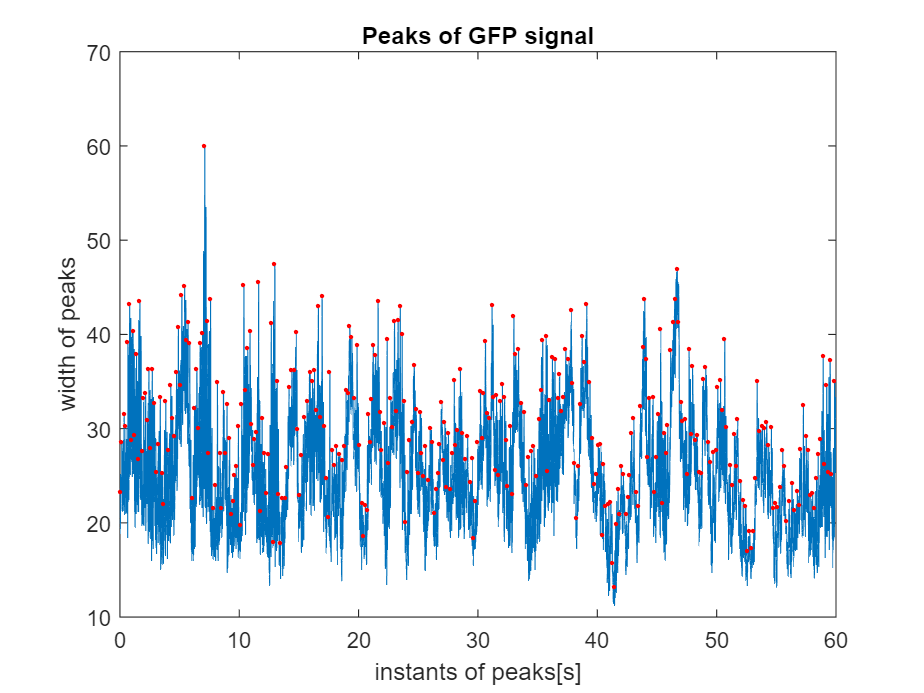

min_time_microstate=0.12;
sample=1/fc;
minpeakheight = 0;
minpeakdistance=min_time_microstate/sample;
[pks,locs] = findpeaks(gfp,'MinPeakHeight',minpeakheight,'MinPeakDistance', minpeakdistance);
figure
plot(time,gfp)
hold on
plot(time(locs),gfp(locs),'.','color','r')
title('Peaks of GFP signal')
ylabel('width of peaks')
xlabel('instants of peaks[s]')
xlim([0 60])

## PCA

PCA is a technique used to define fewer unrelated variables known as principal components from a larger dataset. In order to display our data in less dimention we use the first 2 and 3 components.

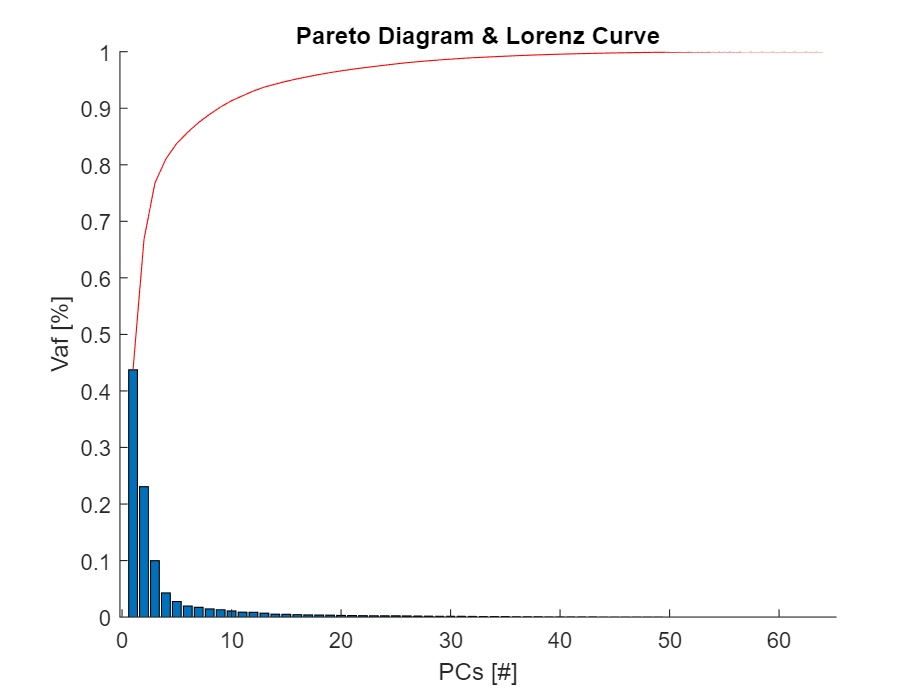

Y=v(:,locs)';
[U,X,S]=pca(Y);

figure
bar(1:length(S),S./sum(S))
hold on
plot(1:length(S),cumsum(S)./sum(S),'Color','r')
title('Pareto Diagram & Lorenz Curve')
xlabel('PCs [#]')
ylabel('Vaf [%]')
box off

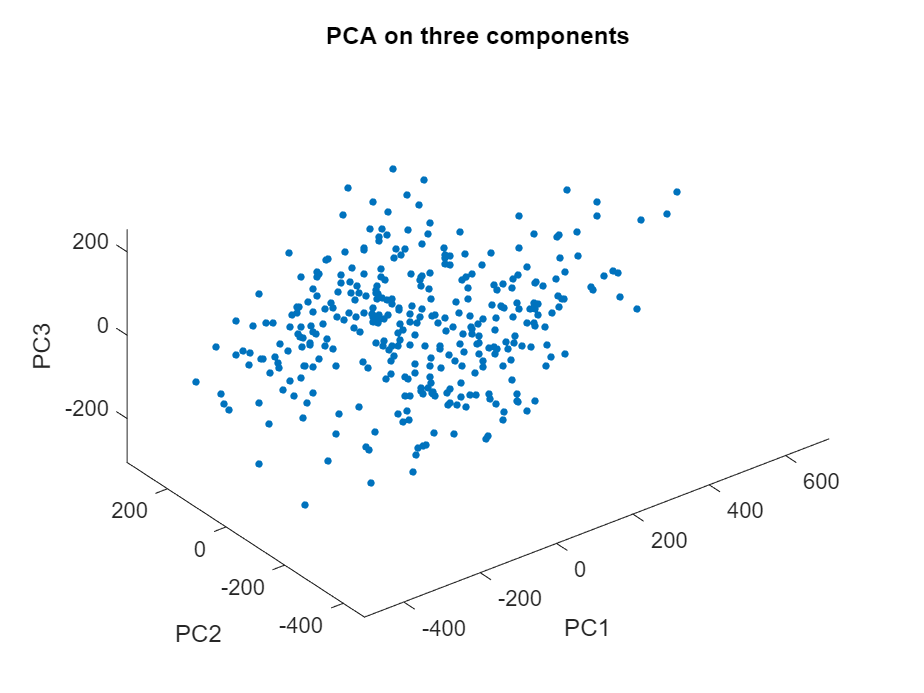

figure
plot3(X(:,1),X(:,2),X(:,3),'.','MarkerSize',10)
title('PCA on three components')
xlabel('PC1')
ylabel('PC2')
zlabel('PC3')
axis equal
box off

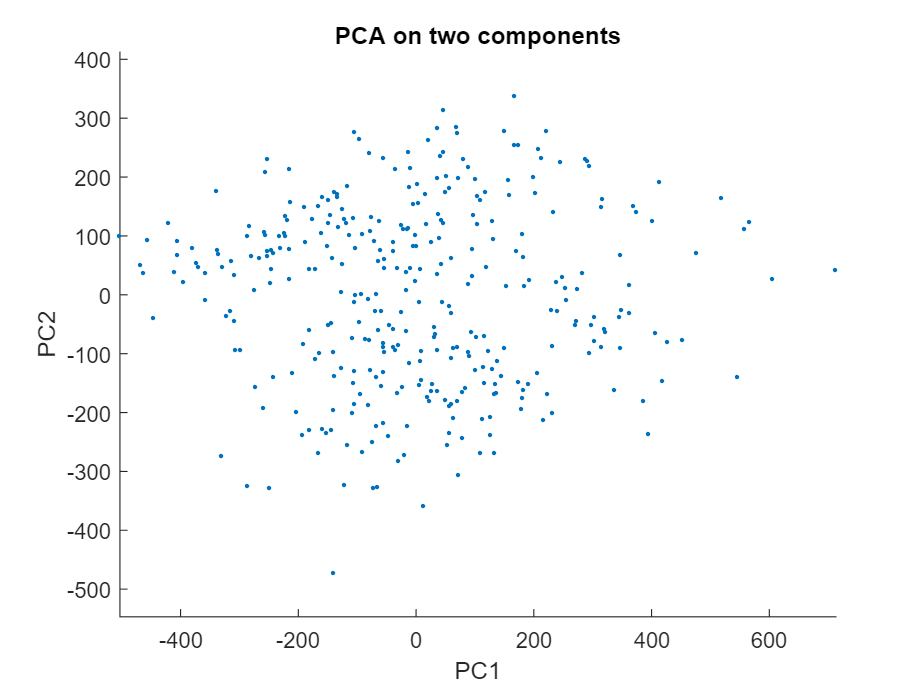

figure
scatter(X(:,1),X(:,2),'marker','.')
title('PCA on two components')
xlabel('PC1')
ylabel('PC2')
axis equal

## Cluster Analysis:

In clustering analysis, topographies at all GFP peaks are simultaneously extracted and entered into a clustering algorithm that groups these maps into a small set of classes based on topographic similarity, without regard to the order of their appearance; then, the topography at each GFP peak is labeled as one of these classes, and the EEG signal is re-expressed as a sequence of microstate classes.(1)

The first thing we do is to calculate the possible number of clusters.

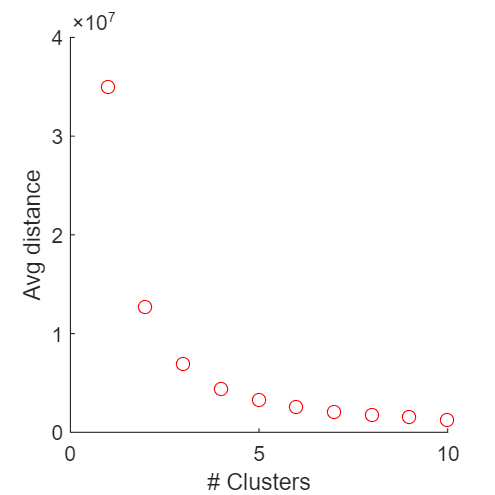

% initializes random number generator so that all runs give same results
seed = 1234;
rng(seed);

n_pks=length(Y);
nk = 10;

idx = zeros(n_pks,nk);
av_sumd = zeros(nk,1);
for k = 1:nk
    [idx(:,k),~,sumd] = kmeans(Y,k);
    av_sumd(k) = mean(sumd);
end
figure('Position',[0 0 300 300])
plot(1:nk,av_sumd,'or')
xlabel('# Clusters')
ylabel('Avg distance')
box off

According to Khanna et al. (2015) our results shows that an optimal number of clusters is 4. Michel et al. (2018) think that the optimal number of clusters should be defined in each dataset individually. So we choose to do the calculation also for 5 clusters and see the differences between the two choices.

nk =4;
idx_final_k = idx(:,nk);

We use two different type of Cluster Analysis:

## K-means

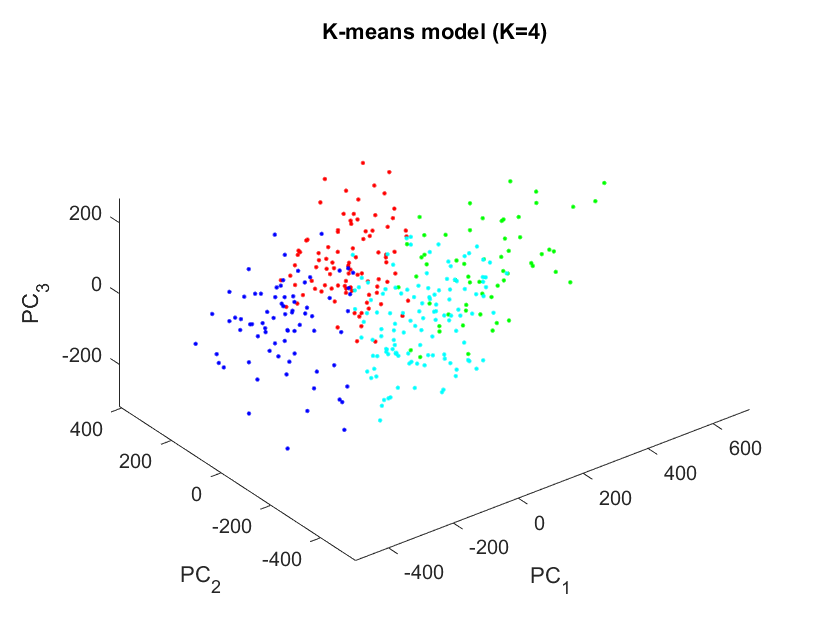

figure
title(sprintf('K-means model (K=%d)',nk))

for i = 1:nk
    is_cluster = find(idx_final_k == i);
   
    line(X(is_cluster,1),...
         X(is_cluster,2),...
         X(is_cluster,3),'marker','.','lines','none','Color',cols{i})
    
end
xlabel('PC_1')
ylabel('PC_2')
zlabel('PC_3')
axis equal
view(3)

## Mixture of Gaussians

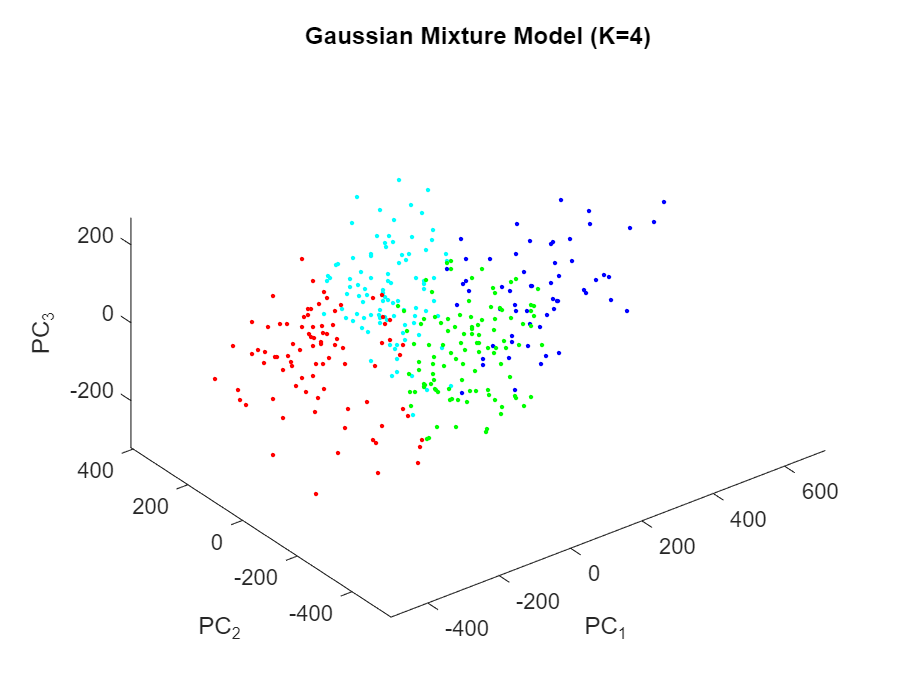

GMModel = fitgmdist(Y,nk,'CovarianceType','diagonal');
idx_final_g = cluster(GMModel,Y);

figure
title(sprintf('Gaussian Mixture Model (K=%d)',nk))
for i = 1:nk
    is_cluster = find(idx_final_g == i);
    line(X(is_cluster,1),...
         X(is_cluster,2),...
         X(is_cluster,3),'marker','.','lines','none','Color',cols{i})
end
xlabel('PC_1')
ylabel('PC_2')
zlabel('PC_3')
axis equal
box off
view(3)

## Heads Plot

Now that we have all data we can plot each microstate topography using eegplot. To calculate the coordinates of all the 64 channels we use the ginput function on the brain2.jpg figure and we put the coordinates in a file that we call 'channels_coordinates'.

% ch      -Channel coordinates from the image. To select channels interactively, 
%          set ch=[] ;. You can use the GINPUT function to get the cordinates of  
%          the channel from the 'brain2.jpg' image and use it in ch ie (3 channels): 
%          brain=imread('brain2.jpg');
%          imshow(brain)
%          [y,x]=ginput(3);
%          ch=[x y];

rootdir='C:\Users\giuse\Desktop\1 ANNO\Analysis\eeg_3';
load(fullfile(rootdir,'eegplotdat'))
ch =load(fullfile(rootdir,'channels_coordinates'));
ch=ch.ch;

We display the microstates according to K-means and GM, in order to see the difference between them.

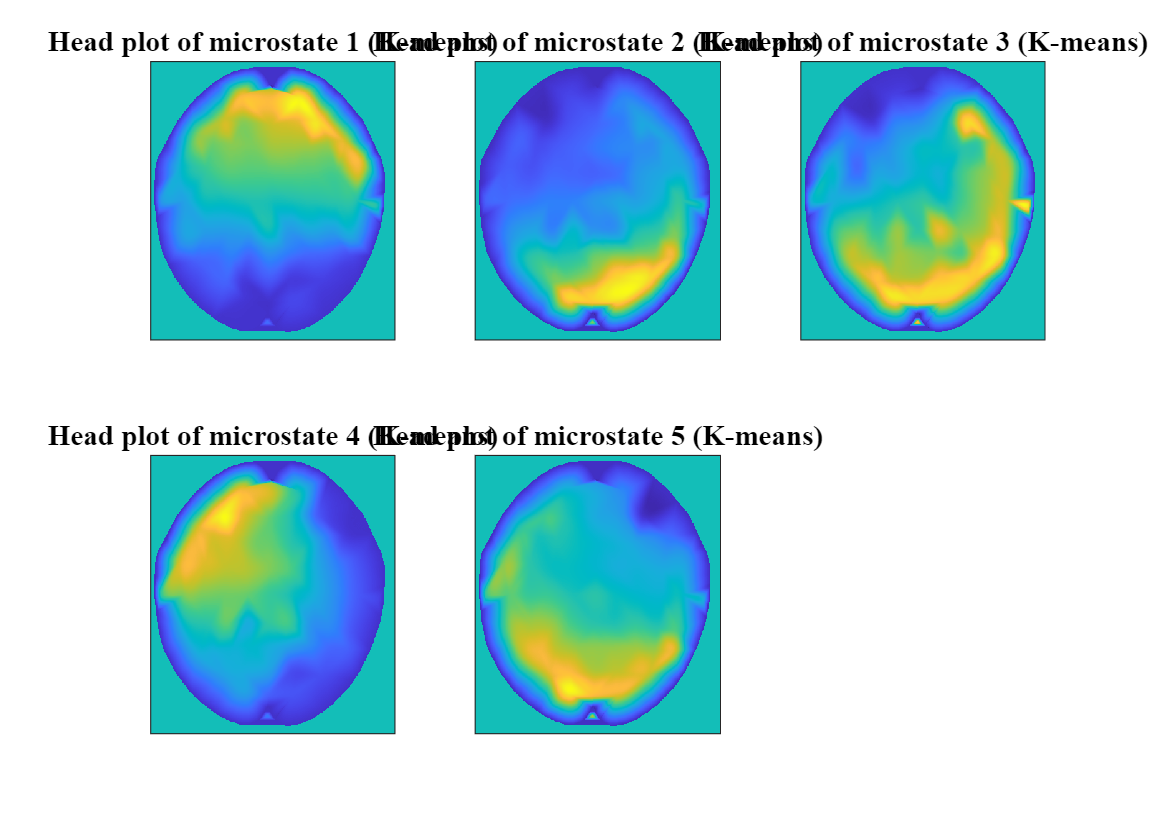

mag_k=magcreator(nk,idx_final_k,Y);
mag_gm=magcreator(nk,idx_final_g,Y);

figure('pos',[0 0 700 500])
tiledlayout(2,nk-2);
for i=1:nk
nexttile
eegplot(mag_k(:,i),ch,[],[],[],[],'default');
title(sprintf('Head plot of microstate %d (K-means)', i))
yticks([])
xticks([])
end

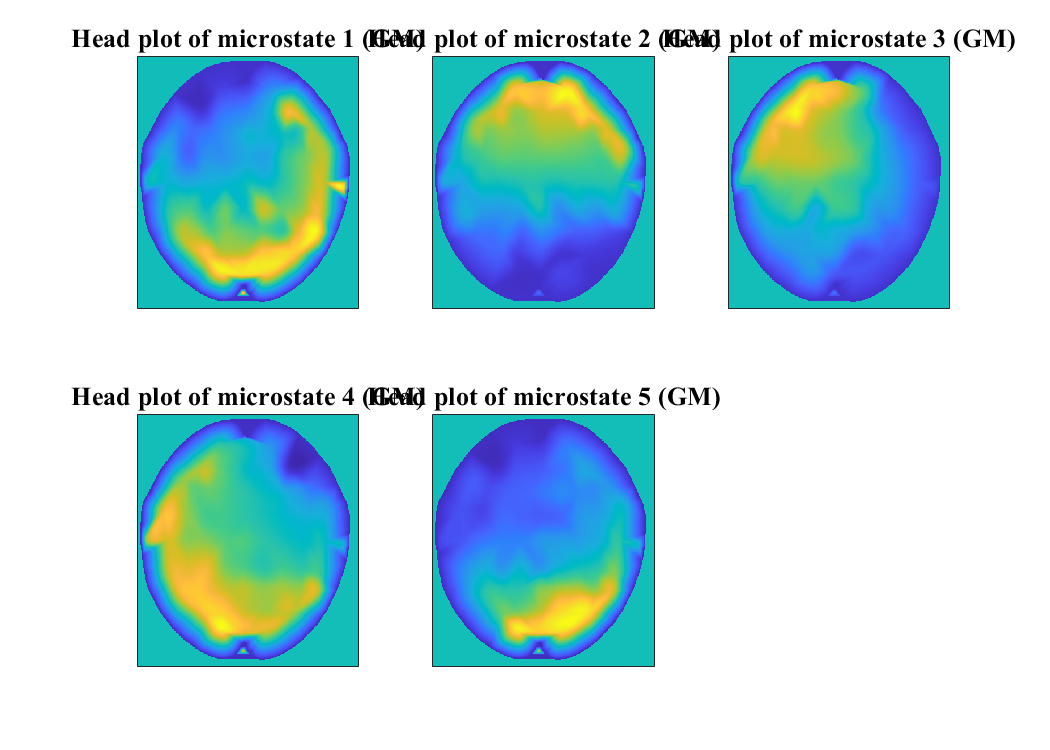

figure('pos',[0 0 700 500])
tiledlayout(2,nk-2);
for i=1:nk
nexttile
eegplot(mag_gm(:,i),ch,[],[],[],[],'default');
title(sprintf('Head plot of microstate %d (GM)', i))
yticks([])
xticks([])
end

Our result show that these four maps have right-frontal left-posterior, left-frontal right-posterior, midline frontal-occipital, and midline frontal topographies. In literature labeled A, B, C, and D.(1) We also try to use 5 clusters but we notice that two microstate's topographies are very similar each other, so we conclude that 4 is a better number.

## Transition of microstates

In the end we display the variation of the microstates for the 60 seconds of the recording.

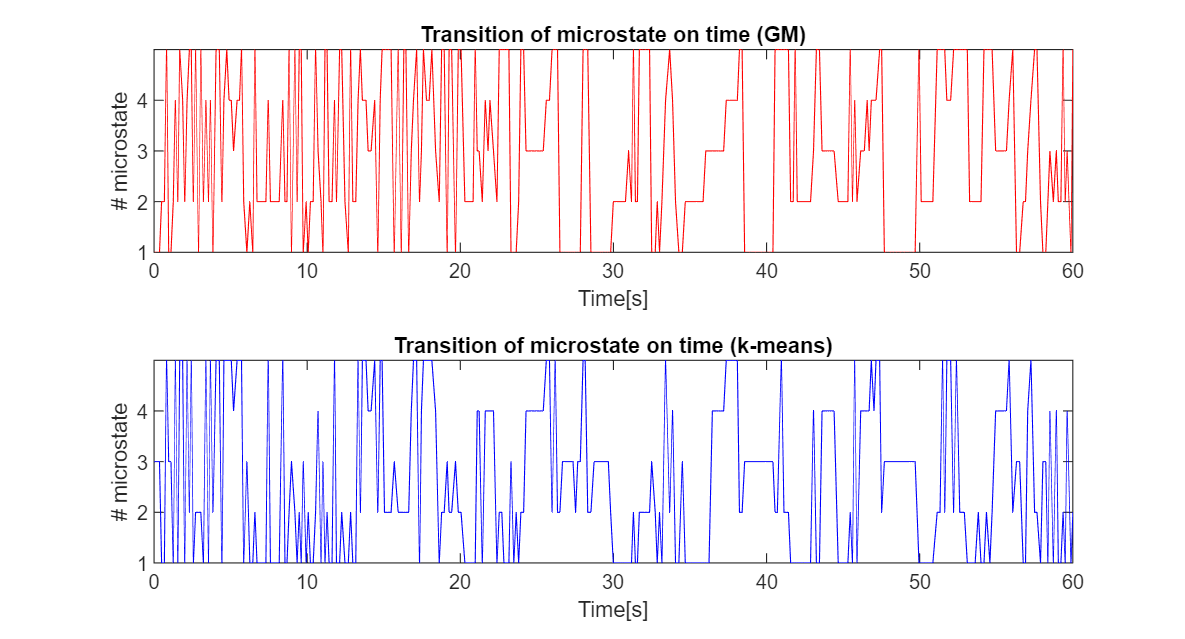

figure('pos', [0 0 1300 700])
tiledlayout(2,1)
nexttile
plot(time(locs),idx_final_g,'r')
title('Transition of microstate on time (GM)')
xlim([0 60])
xlabel('Time[s]')
ylabel('# microstate')
yticklabels({'1','2','3','4'})
yticks([1 2 3 4])

nexttile
plot(time(locs),idx_final_k,'b')
title('Transition of microstate on time (k-means)')
xlim([0 60])
xlabel('Time[s]')
ylabel('# microstate')
yticklabels({'1','2','3','4'})
yticks([1 2 3 4])

## Conclusions

Transitions between microstates may be interpreted to represent sequential activation of different neural networks, and the time series of microstates in resting-state EEG gives us a sense of the rapid switching between the activities of neural assemblies of the brain at rest.(1) Morover, based on Britz et al. (2010), microstate B was shown to be associated with the visual network (VN), while microstate D was related to dorsal attention network (DAN). DAN is often considered as an activity-modulating network in the VN, especially the frontoparietal areas. Microstate C has been shown to be correlated with the brain regions responsible for the self-referential mental activity (e.g., parts of DMN). An increase in the self-referential processes in DMN has been shown to be closely related to depression. Brain regions associated with microstate A have been shown to be involved in the auditory-phonological system, especially the bilateral superior temporal cortex. Such alteration in this RSN has been reported in the meta-analyses for subjects with depression.(2)

## Hidden Markov Models (bonus)

In summary, analysis of the temporal sequence of microstates provides an ideal macroscopic window for observing the temporal dynamics of spontaneous brain activity. For this reason can be interesting to model the microstate sequences using hidden Markov models.(3)

We observed a simple structure in the microstate transition matrix. We found that it can be described with a first order Markov chain which has a simple syntax with only four parameters, assuming that the transition probability from a current map to a next, different map only depends on the next and not on the current map. (4)

We have only one signal of length = number of locs and we assume it as our observable variable. Starting from this we want to calculate the transmission matrix for the hidden states (sequence of microstates - idx_final).

rng(1234); % to make results replicable
t=size(locs,1);
hidden=zeros(t-1,2);
observable=zeros(t-1,2);
data1=gfp(locs);

To use HMM we have to discretize our data.

x=10;
[discr_data,E] = discretize(data1,x);
for i=1:t-1
    hidden(i,:)=[idx_final_g(i) idx_final_g(i+1)];
    observable(i,:)=[discr_data(i) discr_data(i+1)];
end

flag="0";
if flag=='1'
dataset=observable;
else
dataset=hidden;
end

We assume to use a HMM with two 'time' slices and we consider every change of the states a different experiment. So our observable and hidden variables becames a sequence of experiments.

nreps=10;
Phi_est=cell(nreps,1);
E_est=cell(nreps,1);
for rep=1:nreps
    Phi0 = normalize(rand(nk,nk),2,'norm',1); 
    E0 = normalize(rand(nk,x),2,'norm',1);
    [Phi, E]=hmmtrain(dataset,Phi0,E0);
     Phi_est{rep}=Phi;
     E_est{rep}=E;
     totallogL(rep) = 0;
     for ns = 1:t-1
         [posterior,loglik]=hmmdecode(dataset(ns,:),Phi,E);
         totallogL(rep) = totallogL(rep) + loglik;
     end
end

[bestlogL,bestrep]=max(totallogL);
Phi_best = Phi_est{bestrep}

Phi_best =     0.4335    0.1752    0.1492    0.2421
    0.2943    0.6193    0.0864    0.0000
    0.3194    0.0245    0.6107    0.0454
    0.2937    0.1011    0.0000    0.6052


In this way we calculate the best transmission Matrix that indicates the probabilities of transition between hidden states. In Gartner et al. (2015) is shown that the transition probability to any map A, B, C or D from a different map shows virtually no dependence on the preceding map. In this case our results are very different from the ones in literature and they seem to be meaningless. But if we compute the transition matrix directly starting from the hidden dataset - made of the alternation of microstates calculated in the previously part - we notice that results are similar to the one in the paper. This can be seen selecting flag=0.

## Bibliography

(1)  Arjun Khanna et al., Microstates in resting-state EEG: Current status and future directions, Neuroscience & Biobehavioral Reviews, Volume 49, 2015, Pages 105-113, ISSN 0149-7634, [https://doi.org/10.1016/j.neubiorev.2014.12.010](https://doi.org/10.1016/j.neubiorev.2014.12.010)

(2) Al Zoubi Obada et al., EEG Microstates Temporal Dynamics Differentiate Individuals with Mood and Anxiety Disorders From Healthy Subjects, Frontiers in Human Neuroscience, Volume 13, 2019, ISSN 1662-5161, [https://doi.org/10.3389/fnhum.2019.00056](https://doi.org/10.3389/fnhum.2019.00056) 

(3) Christoph M. Michel et al., EEG microstates as a tool for studying the temporal dynamics of whole-brain neuronal networks: A review, NeuroImage, Volume 180, Part B, 2018, Pages 577-593, ISSN 1053-8119, [https://doi.org/10.1016/j.neuroimage.2017.11.062](https://doi.org/10.1016/j.neuroimage.2017.11.062)

(4) Matthias Gärtner et al., A stochastic model for EEG microstate sequence analysis, NeuroImage, Volume 104, 2015, Pages 199-208, ISSN 1053-8119, [https://doi.org/10.1016/j.neuroimage.2014.10.014](https://doi.org/10.1016/j.neuroimage.2014.10.014)